# Ejercicio 2

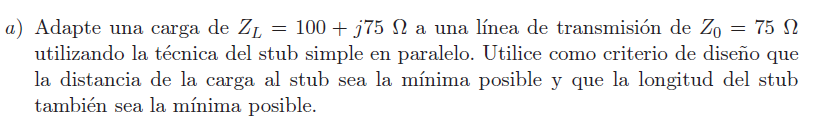

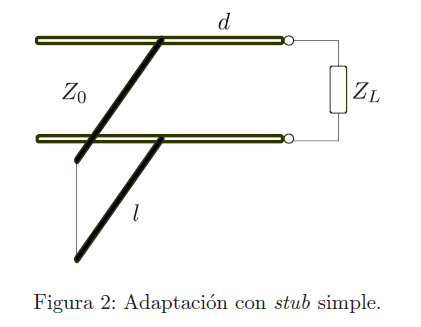

ZL = 100 + 1i*75;
f0 = 100e6;
Zo = 75;
gamma_yL  = z2gamma(1/ZL, 1/Zo);


clf;                                                                         %%clear figure
abaco           = figure();
rfckt_handler   = rfckt.passive;                                             %%elemento de rfckt a dibujar
[h1, hsm]       = circle (rfckt_handler, f0, 'Gamma', abs(gamma_yL),'R',1);
hold on;

%%busco las intersecciones
[ptA, ptB] = imped_match_find_circle_intersections_helper([0 0], abs(gamma_yL), [0.5 0], 0.5);
plot(ptA(1),ptA(2), 'k.','MarkerSize',16);
plot(ptB(1),ptB(2), 'k.','MarkerSize',16);

ptA_mod = norm(ptA);                ptB_mod = norm(ptB);                                %%Compute magnitudes
ptA_ang = atan2(ptA(2), ptA(1));    ptB_ang = atan2(ptB(2), ptB(1));                    %%Compute angles
gamma_A = ptA_mod*exp(1i*ptA_ang);  gamma_B = ptB_mod*exp(1i*ptB_ang);                  %%With it compute gammas
text (real(gamma_A) + .1, imag(gamma_A)-.1, 'P_A','FontSize', 12, 'FontWeight','Bold'); %%graphing points
text (real(gamma_B) + .1, imag(gamma_B)+.1, 'P_B','FontSize', 12, 'FontWeight','Bold');

%%grafico yL
plot(real(gamma_yL), imag(gamma_yL), 'k.','MarkerSize',16);
text (real(gamma_yL) + .05, imag(gamma_yL)-.08, 'y_L','FontSize', 12, 'FontWeight','Bold');



- Como el criterio es la mínima distancia, entonces elegimos P_B

angle(gamma_yL)

ans = -2.2974

ptB_ang

ptB_ang = 1.1426

d_ang   = 2*pi + angle(gamma_yL) - ptB_ang 

d_ang = 2.8431

d       = d_ang*(0.25/pi)

d = 0.2263


y_B     = gamma2z(gamma_B, Zo);                  %%susceptancia de PB
imag_yB = imag(y_B);                             %%Parte imaginaria que tengo que compensar

y_stub      = 1 - (y_B/Zo);
stub        = rfckt.passive;
[h2,hsm]    = circle(stub, f0, 'X', imag(y_stub));     %%Graficamos el stub


%%Saco del gráfico el punto de intersección del stub y R=0
gamma_stub  = z2gamma(y_stub*Zo, Zo);
ang_ptY     = atan2(imag(gamma_stub), real(gamma_stub));                        
ptY         = [real(gamma_stub) imag(gamma_stub)];
plot(ptY(1), ptY(2), 'k.','MarkerSize',16);
text (ptY(1)+.1, ptY(2)+.1, 'y_S','FontSize', 12, 'FontWeight','Bold');
l_stub    = abs(ang_ptY) * (0.25/pi)

l_stub = 0.1322

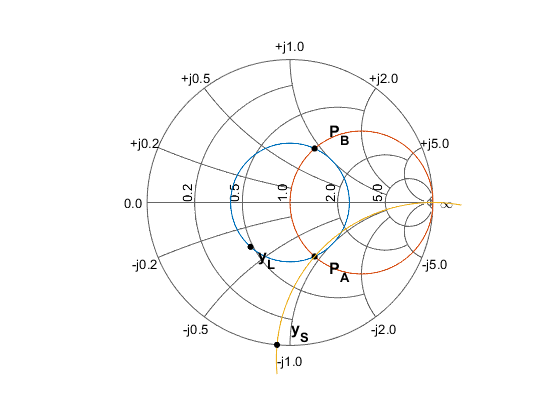


hold off

%RG-59 Pasternack
vf  = 0.66;
b   = 3.71e-3;
a   = 0.56e-3;
er  = 1/vf^2;
tanD = 0.003;                       %%sacado de la guía de la catedra, NO DEL DATASHEET
l   = 100;                          %%checkear, no se especifíca un largo en el tp
Zo_aprox = (60/sqrt(er))*log(b/a)   %%tiene que dar aprox 75 si todos los datos están bien

Zo_aprox = 74.8777


vp          = 3e8/sqrt(er);
lambda_0    = (vp/f0)

lambda_0 = 1.9800


tx_d    = rfckt.coaxial ('OuterRadius', b, 'InnerRadius', a, 'EpsilonR', er,'LineLength', d*lambda_0, 'LossTangent', tanD);
tx_stub = rfckt.coaxial ('OuterRadius', b, 'InnerRadius', a,'EpsilonR', er, 'LineLength', l_stub*lambda_0, 'LossTangent', tanD, 'StubMode', 'Shunt', 'Termination', 'Short');
t_ZL    = rfckt.seriesrlc('R', real(ZL), 'L', imag(ZL)/(2*pi*f0));

stub1CC = rfckt.cascade('Ckts', {tx_stub, tx_d, t_ZL});
f       = linspace(10e6, 200e6, 500);
analyze(stub1CC, f);
abaco_en_frec = figure();
smith(stub1CC, 'S11');

respuesta_frec  = figure();
plot(stub1CC,'S11', 'dB');

saveas(abaco, "ej2_abaco", 'png')

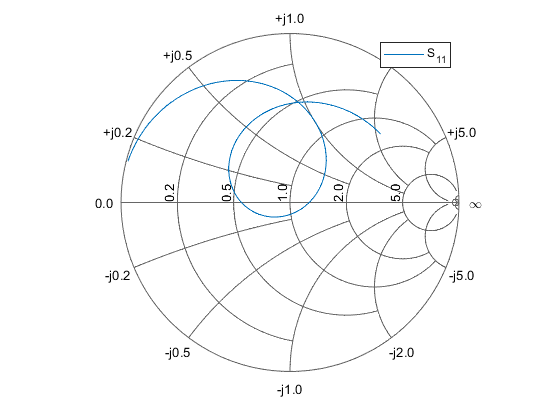

saveas(abaco_en_frec, "ej2_abacoFrec", 'png')

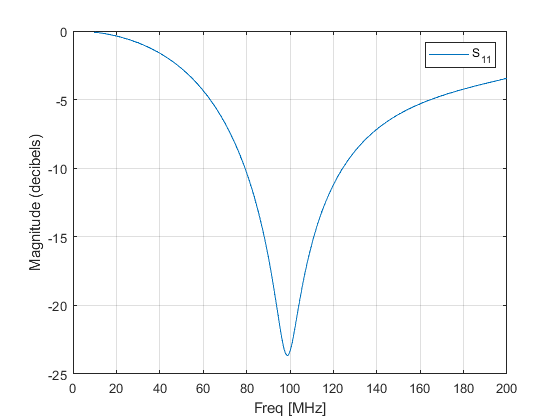

saveas(respuesta_frec, "ej2_RtaFrec", 'png')